# **Predictions of Test Data on Trained Models**

## **Defining Directories and Folders**

% Creating directories to save the predictions
myDir1 = 'ResultsTestDiffChannels/3C-noTL'; 
myDir2 = 'ConfusionMatrix';
myDir3 = 'ROCcurves';
if ~exist(myDir1, 'dir')
    mkdir(['./' myDir1 '/' myDir2])
    mkdir(['./' myDir1 '/' myDir3])
end

% Define folder path for the data
folder = ("C:\MathWorks\themoonrocks\ValidationResults_noTL_3C\Data\");
addpath('.\ValidationResults_noTL_3C\Data');

## **Individual ROCs and Confusion Matrices**

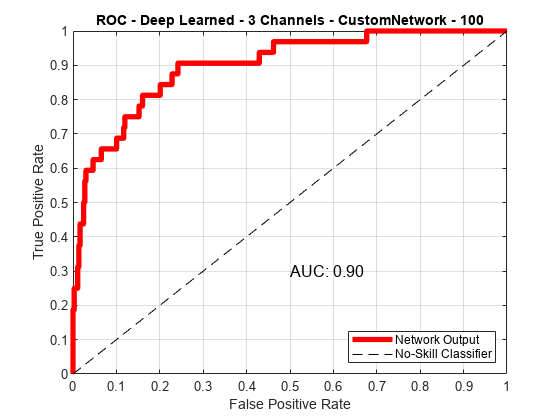

list = dir(fullfile(folder, '*.mat'));
files = {list.name};

global patchSize;
global currentCombination;
global chnr;

for i = 1:numel(files)
    try
        file = fullfile(folder, files{i});
        fileName = files{i};
        data = load(fileName);
        patchSize = data.patchSize;
        currentCombination = [1, 3, 7]; % data.currentCombination;
        chnr = data.chnr;
        ImageLocation = ['C:\Patchestest\Patches' num2str(data.patchSize)]; %define the location the main folder names Patches
        TestImages = imageDatastore(ImageLocation, 'IncludeSubfolders', true, 'LabelSource',...
            'foldernames', 'FileExtensions', '.img', 'ReadFcn', @readPatchWithProcessing);
        real_labels = TestImages.Labels;
        models = data.mynetOSAug;
        [predictedLabels_test, score_test] = classify(models, TestImages);

        % Compute AUC
        [X, Y, ~, AUC] = perfcurve(real_labels, score_test(:,2), ['sinuous-rille-' num2str(patchSize) '-' num2str(patchSize)]);
        
        % Plot ROC curve
        h = figure;
        plot(X, Y, 'r', 'LineWidth', 4); % ROC curve
        hold on;
        plot([0,1], [0,1], 'k--'); % No skill classifier
        xlabel('False Positive Rate');
        ylabel('True Positive Rate');
        title(['ROC - Deep Learned - ' num2str(chnr) ' Channels - ' fileName(1:end-7) ' - ' num2str(patchSize)]);
        grid on;
        
        % Add legend and AUC text
        legend('Network Output', 'No-Skill Classifier', 'Location', 'southeast');
        text(0.5, 0.3, sprintf('AUC: %.2f' , AUC), 'Units', 'normalized', 'FontSize', 12);

        % Save ROC curve figure
        saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', fileName(1:end-7) '-' num2str(chnr) 'C-noTL-' num2str(patchSize) '_ROC.png']));
        saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', fileName(1:end-7) '-' num2str(chnr) 'C-noTL-' num2str(patchSize) '_ROC.fig']));
        close(h);

        % Plot and save confusion matrix
        fig = plotconfusion(real_labels, predictedLabels_test);
        title(['Test - Deep Learned-' num2str(chnr) 'Channels-' fileName(1:end-7) '-' num2str(patchSize)]);
        saveas(fig, fullfile(['./' myDir1 '/' myDir2 '/', fileName(1:end-7) '-' num2str(chnr) 'C-noTL-' num2str(patchSize) '_CM.png']));
        saveas(fig, fullfile(['./' myDir1 '/' myDir2 '/', fileName(1:end-7) '-' num2str(chnr) 'C-noTL-' num2str(patchSize) '_CM.fig']));
        close(fig);
    catch ME
        disp(['Error processing ' fileName ': ' ME.message]);
    end
end

## **Plotting all the ROC Curves of all Trained Models**

% list = dir(fullfile(folder, '*.mat'));
% files = {list.name};
% model = cell(numel(files),1);
% TestImage = cell(numel(files),1);
% real_label = cell(numel(files),1);
% predictedLabels = cell(numel(files),1);
% scores = cell(numel(files),1);
% accuracies = zeros(numel(files),1);
% AUCs = zeros(numel(files),1);
% 
% global patchSize;
% global currentCombination;
% global chnr;
% 
% h = figure;
% hold on;
% for i = 1:numel(files)
%     try
%         file = fullfile(folder, files{i});
%         fileName = files{i};
%         data = load(fileName);
%         patchSize = data.patchSize;
%         currentCombination = data.currentCombination;
%         chnr = data.chnr;
%         ImageLocation = ['C:\Patchestest\Patches' num2str(data.patchSize)]; %define the location the main folder names Patches
%         TestImages = imageDatastore(ImageLocation, 'IncludeSubfolders', true, 'LabelSource',...
%             'foldernames', 'FileExtensions', '.img', 'ReadFcn', @readPatchWithProcessing);
%         real_labels = TestImages.Labels;
%         TestImage{i} = TestImages;
%         models = data.mynetOSAug;
%         model{i} = models;
%         [predictedLabels_test, score_test] = classify(models, TestImages);
%         predictedLabels{i} = predictedLabels_test;
%         scores{i} = score_test;
%         accuracies(i) = mean(predictedLabels_test == real_labels);
% 
%         Compute AUC
%         labels = string(TestImage{i}.Labels);
%         positive_index = find(startsWith(labels, 'sinuous-rille-'), 1);
%         if ~isempty(positive_index)
%             positive_class_label = labels(positive_index);
%             [~, ~, ~, AUC] = perfcurve(labels, scores{i}(:,2), positive_class_label);
%             AUCs(i) = AUC;
%         end
% 
%         Plot ROC curve
%         if ~isempty(positive_index)
%             [fpr, tpr, ~] = perfcurve(labels, scores{i}(:,2), positive_class_label);
%             plot(fpr, tpr, 'LineWidth', 3);
%         end
%     catch ME
%         disp(['Error processing ' fileName ': ' ME.message]);
%     end
% end
% 
% Plot no-skill classifier
% plot([0, 1], [0, 1], '--k');
% 
% xlabel('False Positive Rate');
% ylabel('True Positive Rate');
% title(['ROC Curves Comparision - Deep Learned - ' num2str(chnr) ' Channels']);
% 
% Display AUC values in the legend
% legend_strings = cell(numel(files), 1);
% for i = 1:numel(files)
%     filename_without_extension = erase(files{i}, '.mat');
%     legend_strings{i} = sprintf('%s (AUC=%.2f)', filename_without_extension(1:end), AUCs(i));
% end
% 
% legend_strings = [legend_strings; 'No-Skill Classifier']; % Add the no-skill classifier entry
% 
% legend(legend_strings, 'Location', 'southeast');
% saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', 'All_ROC_' num2str(chnr) 'C-noTL.png']));
% saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', 'All_ROC_' num2str(chnr) 'C-noTL.fig']));
% 
% hold off;

## **Plotting all the ROC Curves of only specific patchSized Trained Models**

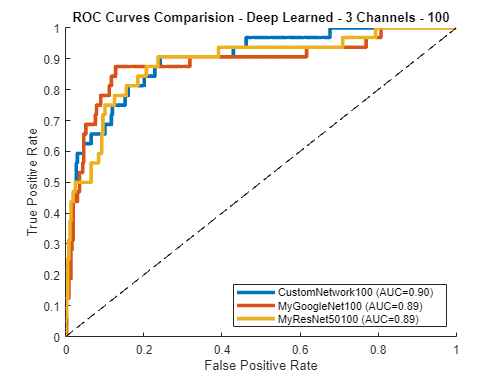

list = dir(fullfile(folder, '*.mat'));
files = {list.name};
model = cell(numel(files),1);
TestImage = cell(numel(files),1);
real_label = cell(numel(files),1);
predictedLabels = cell(numel(files),1);
scores = cell(numel(files),1);
accuracies = zeros(numel(files),1);
AUCs = zeros(numel(files),1);

global patchSize;
global currentCombination;
global chnr;

% Initialize legend strings
legend_strings = {};

h = figure; % Create a new figure
hold on;
for i = 1:numel(files)
    try
        if contains(files{i}, '100')
            file = fullfile(folder, files{i});
            fileName = files{i};
            data = load(fileName);
            patchSize = data.patchSize;
            currentCombination = [1, 3, 7]; % data.currentCombination;data.currentCombination;
            chnr = data.chnr;
            ImageLocation = ['C:\Patchestest\Patches' num2str(data.patchSize)]; %define the location the main folder names Patches
            TestImages = imageDatastore(ImageLocation, 'IncludeSubfolders', true, 'LabelSource',...
                'foldernames', 'FileExtensions', '.img', 'ReadFcn', @readPatchWithProcessing);
            real_labels = TestImages.Labels;
            TestImage{i} = TestImages;
            models = data.mynetOSAug;
            model{i} = models;
            [predictedLabels_test, score_test] = classify(models, TestImages);
            predictedLabels{i} = predictedLabels_test;
            scores{i} = score_test;
            accuracies(i) = mean(predictedLabels_test == real_labels);

            % Compute AUC
            labels = string(TestImage{i}.Labels);
            positive_index = find(startsWith(labels, 'sinuous-rille-'), 1);
            if ~isempty(positive_index)
                positive_class_label = labels(positive_index);
                [~, ~, ~, AUC] = perfcurve(labels, scores{i}(:,2), positive_class_label);
                AUCs(i) = AUC;
            end

            % Plot ROC curve and display AUC
            if ~isempty(positive_index)
                [fpr, tpr, ~] = perfcurve(labels, scores{i}(:,2), positive_class_label);
                plot(fpr, tpr, 'LineWidth', 3); % Plot ROC curve
                filename_without_extension = erase(files{i}, '.mat');
                legend_strings{end+1} = sprintf('%s (AUC=%.2f)', filename_without_extension, AUCs(i)); % Add legend entry
            end
        end
    catch ME
        disp(['Error processing ' fileName ': ' ME.message]);
    end
end

% Add no-skill classifier
plot([0, 1], [0, 1], '--k');

% Display AUC values in the legend
legend(legend_strings, 'Location', 'southeast');

xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curves Comparision - Deep Learned - ' num2str(chnr) ' Channels - ' num2str(data.patchSize)]);

% Save the figure after plotting ROC curves for 'patchSized' models
saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', num2str(patchSize) '_ROC_' num2str(chnr) 'C-noTL.png']));
saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', num2str(patchSize) '_ROC_' num2str(chnr) 'C-noTL.fig']));

hold off;